# Data Processing MATLAB

WEEK 1 QUIZ 1

IMPORT FILE FLIGHTS JANUARY!

Question 1:

Use the importFlightsData function to import the data for January 2015. Answer questions 1-4 using this data. 

Which origin airport had the greatest number of scheduled flights? Provide your answer using the corresponding 3-letter origin airport code.

mode(flightsJan.ORIGIN)

ans = categorical
     ATL 


Question 2

From which airport do departing flights fly the shortest average distance?

T = groupsummary(flightsJan,"ORIGIN","mean","DISTANCE");
T = sortrows(T,'mean_DISTANCE','ascend')

T = 312×3 table
    ORIGIN    GroupCount    mean_DISTANCE
    ______    __________    _____________

     WRG          62             56.5    
     PSG          62               77    
     CSG          80               83    
     CLD         204               86    
     ACT         147               89    
     PUB          53              109    
     LAR          62              113    
     SPS         106              113    
     TYR         193           115.27    
     BRD          54           115.44    
     MKG          62              118    
     FLG         142              119    
     SIT          92           124.65    
     VEL          53              132    
     SMX          60              134    
     GGG          54              140    


T.ORIGIN(1)

ans = categorical
     WRG 


clear T;

Question 3

What was the total number of flights cancelled in January of 2015?

disp(["Answer: " sum(flightsJan.CANCELLED)]);

    "Answer: "    "11982"



Question 4

What type of distribution do you see when creating a histogram of the TAXI_OUT variable in the flights dataset? 

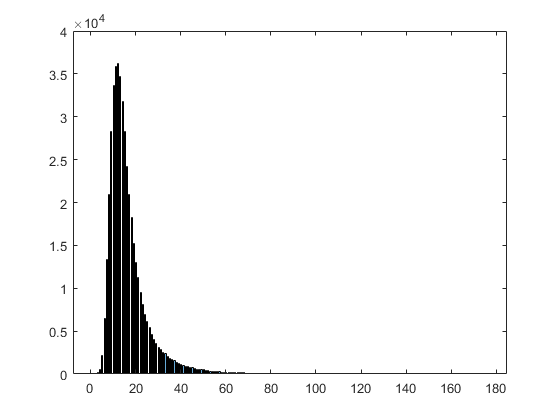

histogram(flightsJan.TAXI_OUT)

disp("Right Skewed")

Right Skewed


Question 5

Use the following image to answer questions 5 - 7. Enter the letter for the image that answers the question.

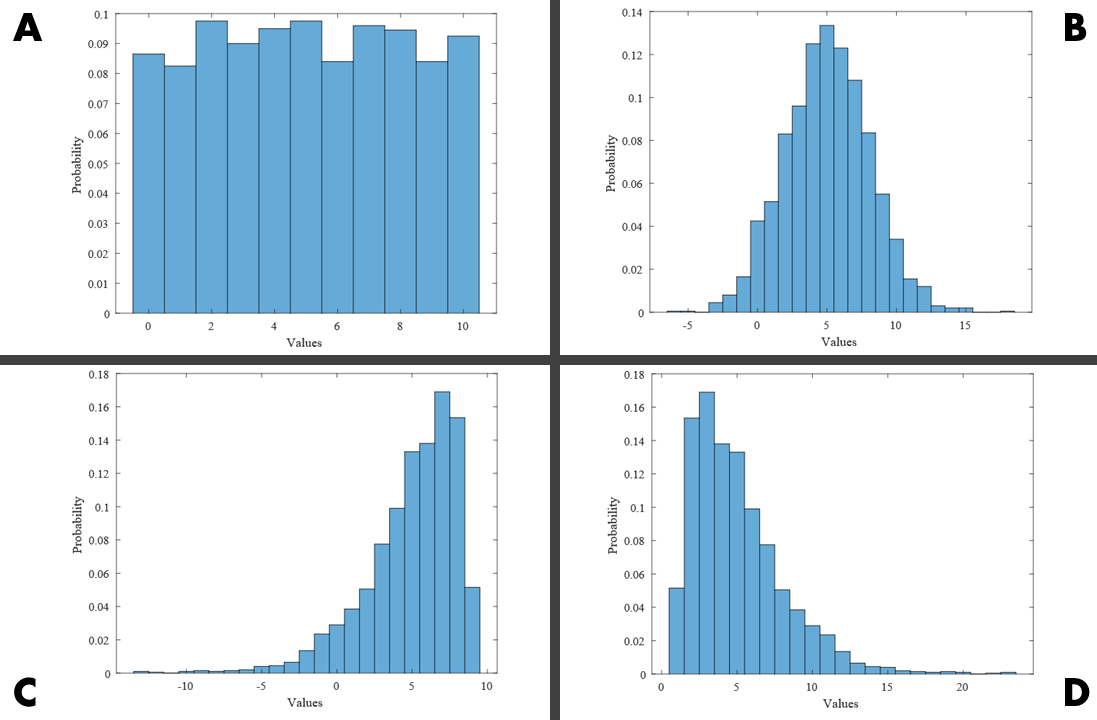

Which plot has negative skewness?

C

Question 6

Which distribution displays an equal probability for all possible values?

A

Question 7

Which distribution above has a kurtosis value of 3? Refer back to [Examples of Distributions ](https://www.coursera.org/learn/feature-engineering-matlab/lecture/9aTnr/examples-of-distributions)video if necessary.

B

Question 8

The box plots below show four different distributions. From left to right, which option below lists the distributions shown?

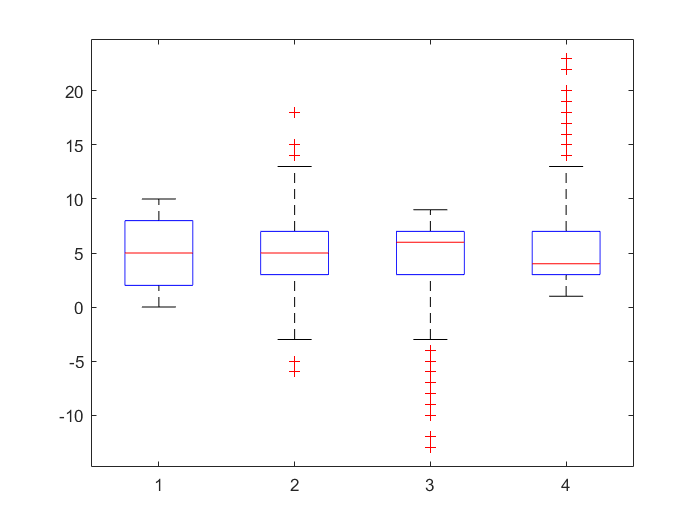

Uniform, Normal, Left Skewed, Right Skewed

Question 9

In the box plot above, the red line inside the box represents what?

median

Question 10

In the box plot above, the red +'s are classified as what?

Outliers

Question 11

Which plot type should be used to visualize the center of a distribution using the interquartile range?

box plot

Question 12

Which visualization function allows you to view each combination of numeric variables in your dataset at once?

gplotmatrix